files = {'hod_m.wav', 'hod_f.wav'};

function [audio, fs, duration, numSamples] = playAudio(fileName)
    filePath = strcat('speech/',fileName);
    [audio, fs] = audioread(filePath);
    duration = length(audio) / fs;
    numSamples = length(audio);
    fprintf('Playing %s at %d Hz with duration %.2f seconds and %d samples\n',fileName, fs, duration, numSamples);
    
    % plot the spectrogram
    figure;
    subplot(2,1,1);
    spectrogram(audio, hamming(960), 240, 1024, fs, 'yaxis');
    title(['Spectrogram of ', fileName]);
    
    % plot the waveform
    subplot(2,1,2);
    time = (0: numSamples - 1) / fs;
    plot(time, audio);
    title(['Waveform of ', fileName])
    sound(audio, fs);
    pause(duration + 1)

    % plot the spectrum as well
end

Playing hod_m.wav at 24000 Hz with duration 0.22 seconds and 5380 samples


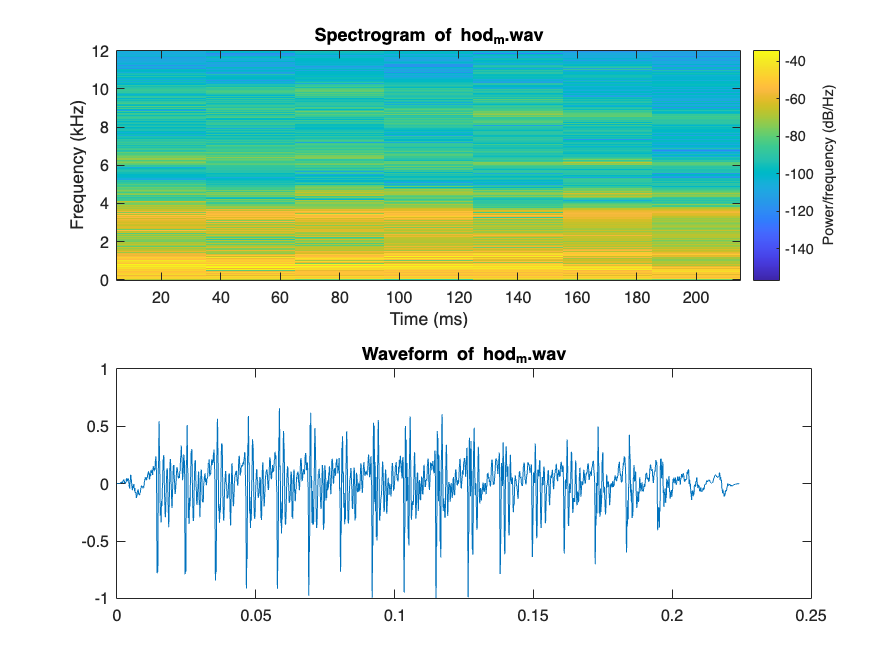

Playing hod_f.wav at 24000 Hz with duration 0.24 seconds and 5763 samples


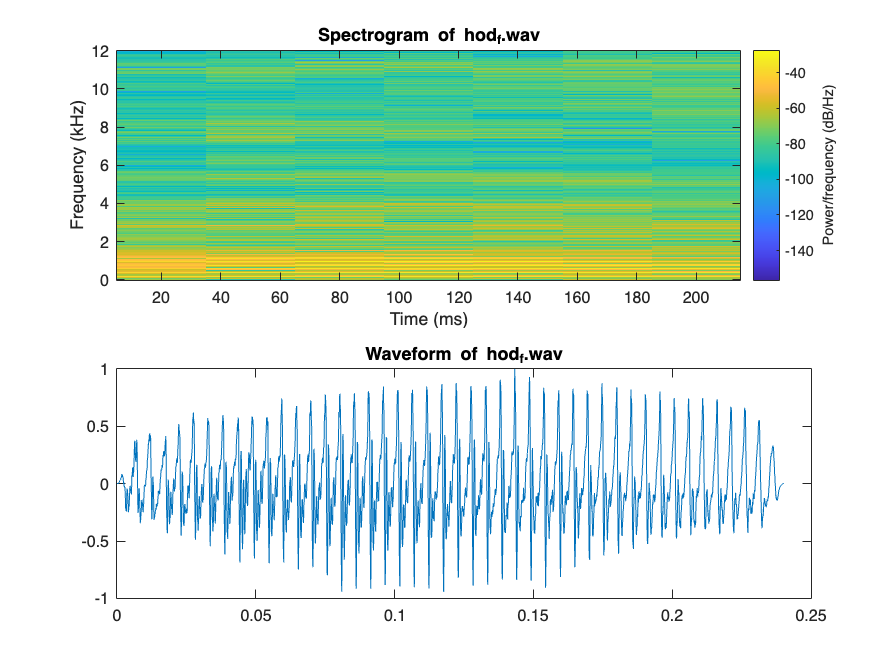

for i = 1:length(files)
    [audio, fs, duration, numSamples] = playAudio(files{i});  % Use the index i to access files
    numSegmentSamples = segmentDuration * fs;
end

% select a 100ms quasi-stationary segment
segment_duration = 0.1

segment_duration = 0.1000

startSample = round(length(audio) / 2) - round(numSamples / 2);  % Middle of the audio
segment = audio(startSample:startSample + numSamples - 1);  % 100ms segment

Array indices must be positive integers or logical values.

figure;
plot((0:numSample-1) / fs, segment);
title('Selected 100ms Segment of hood_m.wav');
xlabel('Time (s)');
ylabel('Amplitude');



% estimate LPC coefficients and find formant frequencies as well as f0


% use filter function to generate speech synthesis using f0 and lpc
% coefficients.
% impulse train is generated using fundamental frequencies (try sawtooth)